**(1)**

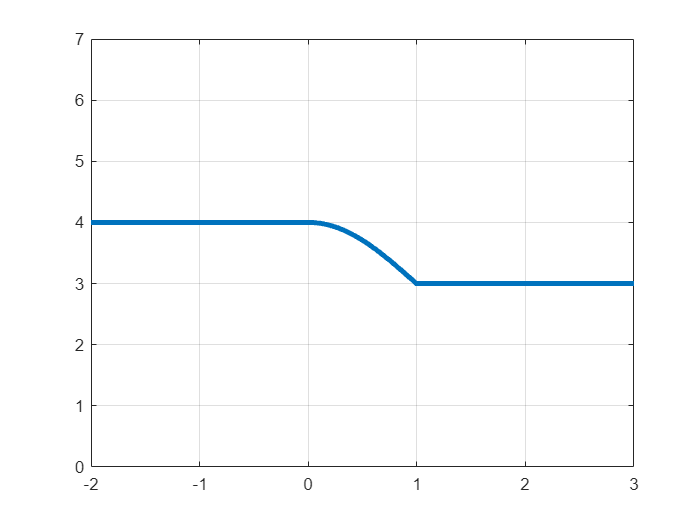

t=linspace(-2,3,500);
t2=linspace(0,1,100);
x1=4*ones(1,200);
x2=cos(2*pi*0.25*t2)+3;
x3=3*ones(1,200);
x=[x1 x2 x3];
plot(t,x, 'LineWidth',3);
grid('on')
ylim([0 7]);

**(2)**

x=linspace(0.001,10,100);
y1=sin(x)./x;
y2=((x-1).^-2)+x;
y3=((x.^2)+1)./((x.^2)-4);
y4=((10-x).^(1/3)-2)./(4-x.^2).^0.5;
subplot(2,2,1);
plot(x,y1);
subplot(2,2,2);
plot(x,y2);
subplot(2,2,3);
plot(x,y3);
subplot(2,2,4);
plot(x,y4);

**(3)**

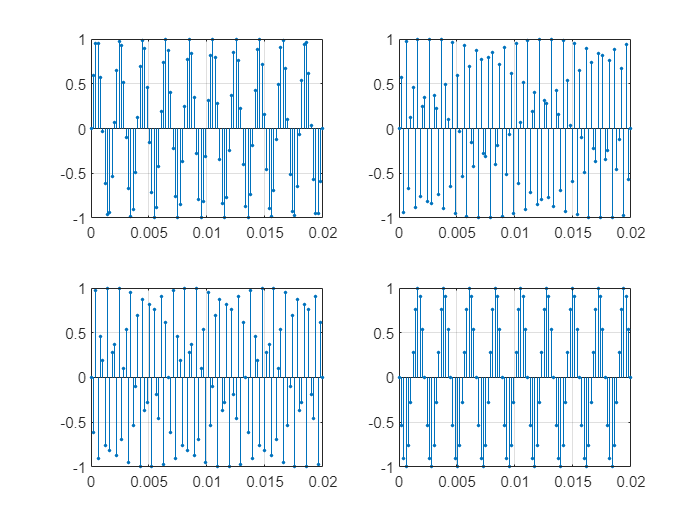

n=linspace(0,0.02,100);
x1= sin(2*pi*500*n);
x2=sin(2*pi*2000*n);
x3=sin(2*pi*3000*n);
x4=sin(2*pi*4500*n);
subplot(2,2,1)
stem(n,x1,'.')
grid on
subplot(2,2,2)
stem(n,x2,'.')
grid on
subplot(2,2,3)
stem(n,x3,'.')
grid on
subplot(2,2,4)
stem(n,x4,'.');
grid on

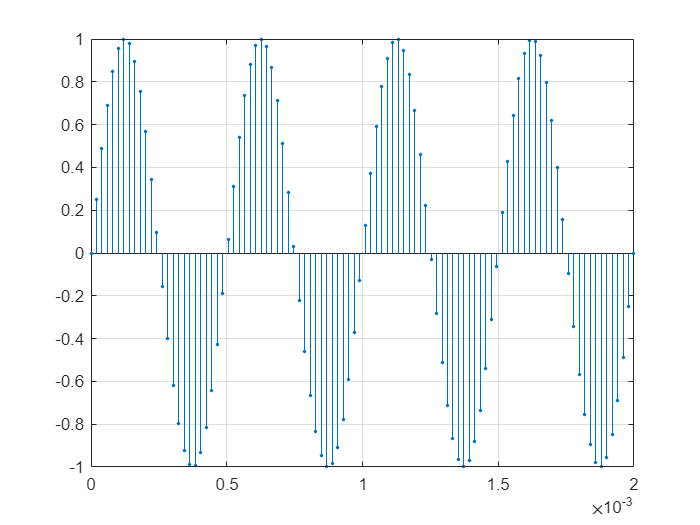


n=linspace(0,0.002,100);
x= sin(2*pi*2000*n);
figure
stem(n,x,'.');
grid on

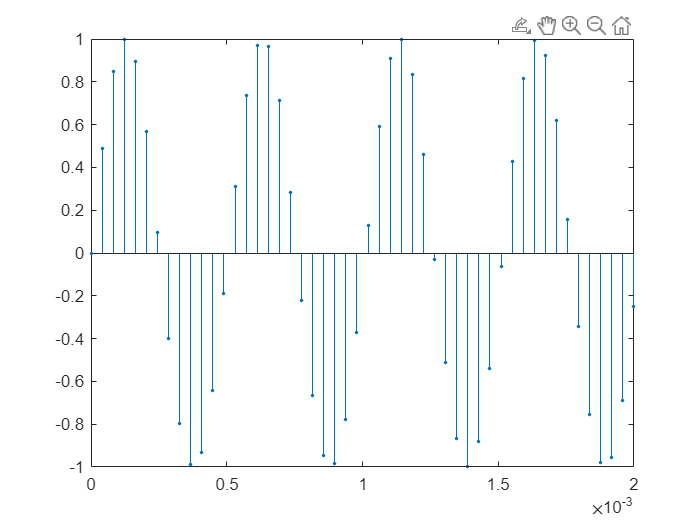

y=downsample(x,2);
n=linspace(0,0.002,50);
figure
stem(n,y,'.');

**(4)**

n=0:1:19;
x=cos(2*n/3);
y=cos(8*pi*n/38);
subplot(2,2,1)
stem(n*2,x)
t=0:0.001:40;
x=cos(2*t/3);
subplot(2,2,2)
plot(t,x)
subplot(2,2,3)
stem(n*2,y)
t=0:0.001:40;
y=cos(4*pi*t/38);
subplot(2,2,4)
plot(t,y)

(5)

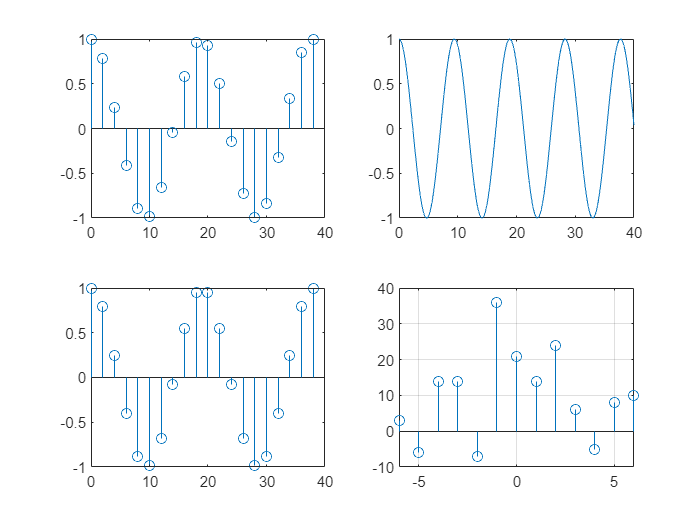

n=-6:1:6;
x=[1,-2,4,6,-5,8,10];
y1=x;
y1(1,8:13)=0;
y2=[0 0 0 0 0 0 x];
x1=3*y1+y2+2*[0 0 x 0 0 0 0];
stem(n,x1);
grid on;

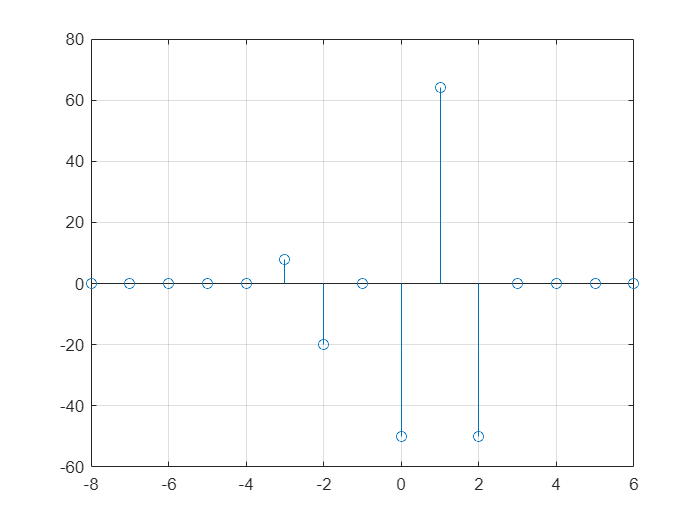

y3=[0 0 0 0 0 x];
y4=x;
y4(1,end+1:end+5)=0;
y5=[x 0 0 0 0];
y5=y5(1,end:-1:1);
y6=[x 0 0 0 0];
y7=y6.*y5;
y8=y3.*y4;
x2=[y8 0 0 0]+[0 0 0 0 y7];
figure
stem(-8:1:6,x2);
grid on;

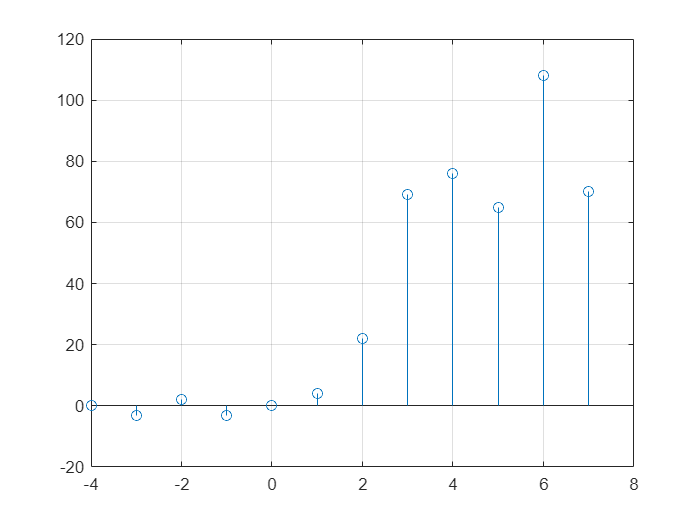

y1=[0 x 0 0 0 0];
y2=[0 0 x 0 0 0];
y3=[0 0 0 x 0 0];
y4=[0 0 0 0 x 0];
y5=[0 0 0 0 0 x];
x3=(y1+y2+y3+y4+y5).*(-4:1:7);
figure
stem(-4:1:7,x3);
grid on;

(6)

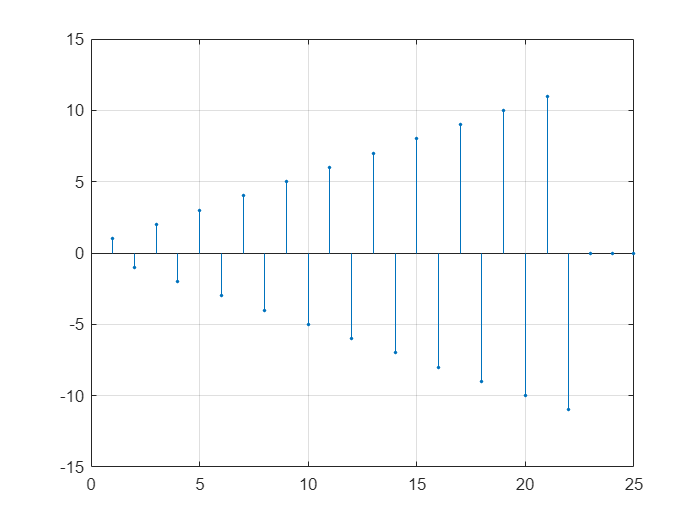

x1=[1 -1 2 -2 3 -3 4 -4 5 -5 6 -6 7 -7 8 -8 9 -9 10 -10 11 -11 0 0 0];
n=1:1:25;
stem(n,x1,'.')
grid on

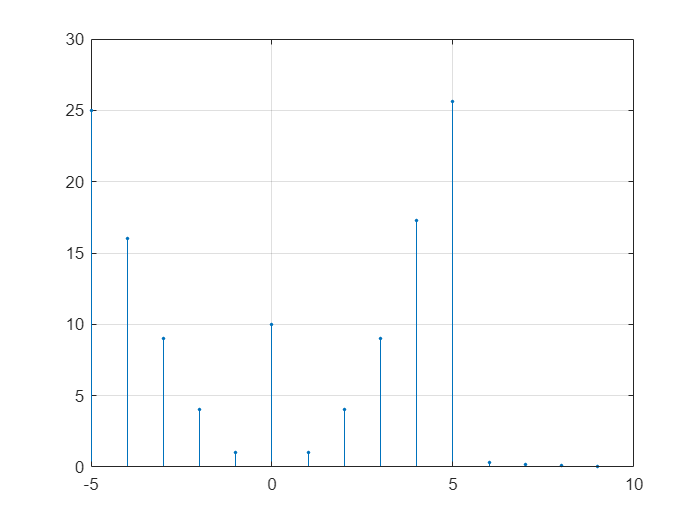


y1=[(5:-1:1).^2 10 (1:1:5).^2 0 0 0 0];
y2=20*[0 0 0 0 0 0 0 0 0 0.5.^(4:1:9)];
x2=y1+y2;
n=-5:1:9;
figure
stem(n,x2,'.')
grid on

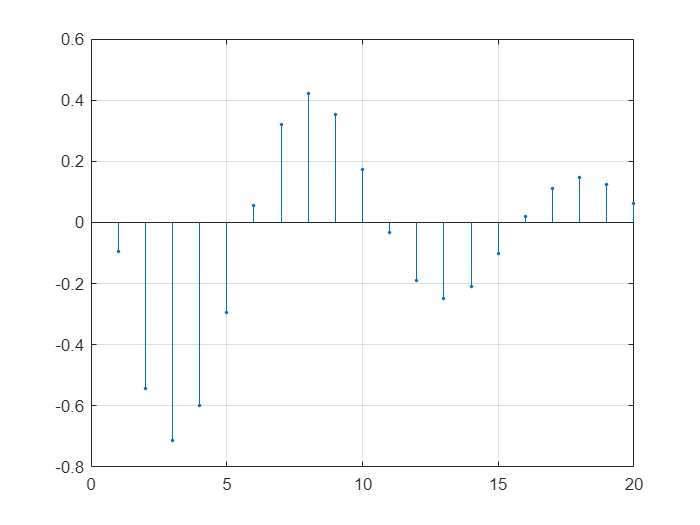


n=1:1:20;
x3=(0.9.^n).*cos(0.2*pi*n+pi/3);
figure
stem(n,x3,'.')
grid on

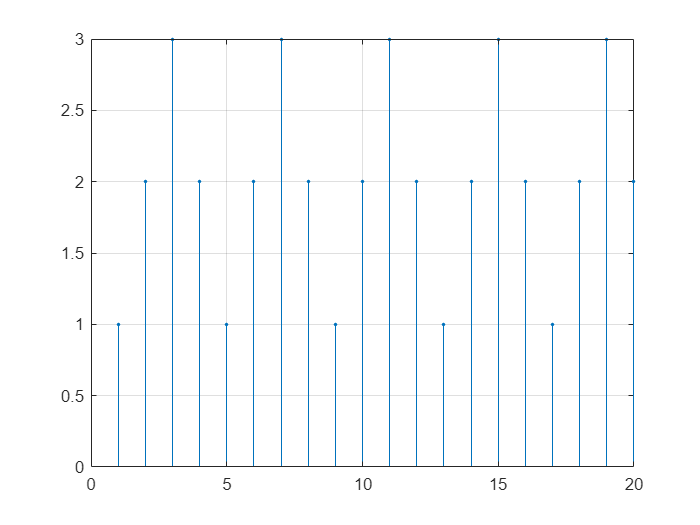


x=[1 2 3 2];
x4=[x x x x x];
figure
stem(x4,'.')
grid on

(7)

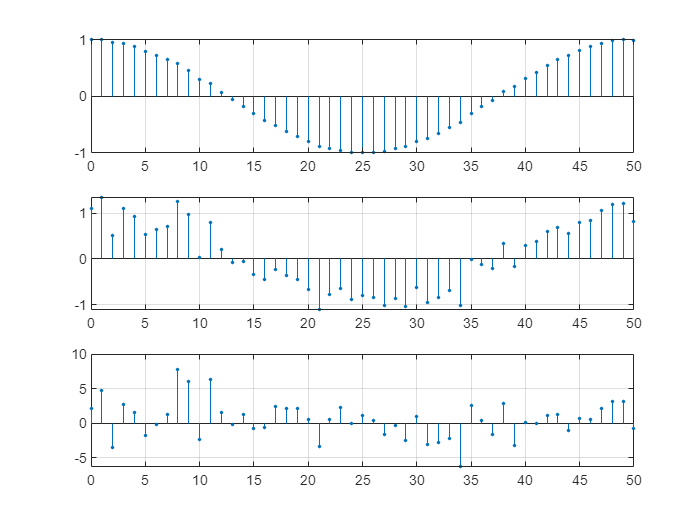

n=0:1:50;
w=randn([1 51]);
x=cos(0.04*pi*n)+0.01*w;
figure
subplot(3,1,1)
stem(n,x,'.')
grid on
x=cos(0.04*pi*n)+0.2*w;
subplot(3,1,2)
stem(n,x,'.')
grid on
x=cos(0.04*pi*n)+2*w;
subplot(3,1,3)
stem(n,x,'.')
grid on

(8)

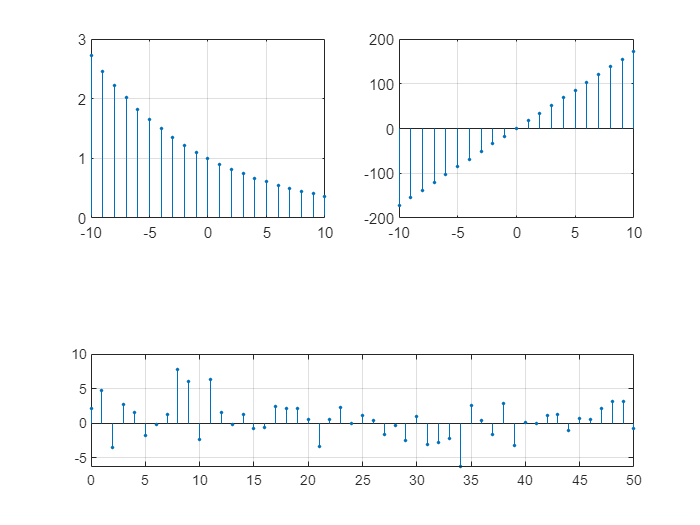

n=-10:1:10;
x=exp((-0.1+0.3i).*n);
subplot(2,2,1)
stem(n,abs(x),'.')
grid on
subplot(2,2,2)
stem(n,angle(x)*180/pi,'.')
grid on

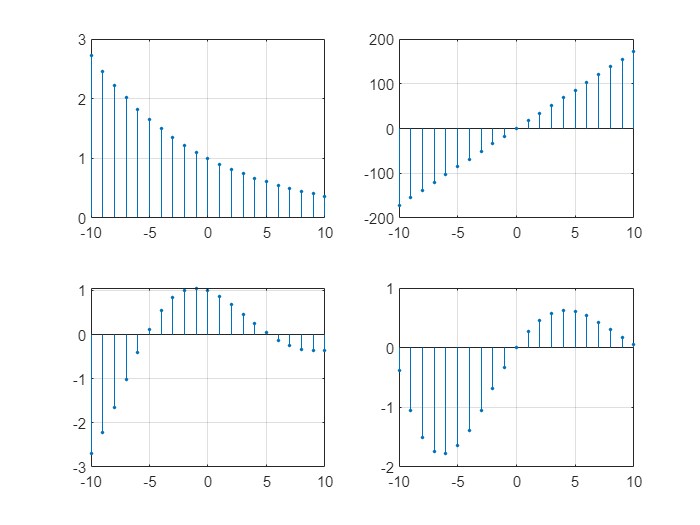

subplot(2,2,3)
stem(n,real(x),'.')
grid on
subplot(2,2,4)
stem(n,imag(x),'.')
grid on